clear;clc;

## 01 读取数据

load("PointFangXing.mat")
PAB = [-0.176,-0.06,0.6]';
P_bound1 = [-0.142,0.47,0.061]*2;
P_bound2 = [0.57,-0.48,0.138];
phi = pi./3;
phi = pi./2 - phi;
shenglunum = 6;
a = 0.015*ones(1,shenglunum);

## 02 计算平面参数（函数planefit4）

[PlaneParaOut,TrianglePoints] = planefit4(face3_transformed,face1_transformed,face4_transformed,face2_transformed,P_bound1,P_bound2);

## 03 计算管路参数 （函数Calculate_rectangle_from_vertex）

[Pin,Pout,UPP,b,h,w,Tao,PP] = Calculate_rectangle_from_vertex(TrianglePoints)

Pin =    -0.3587
    0.8961
    0.0999


Pout =     0.4685
   -0.5394
    0.1001


UPP =     0.0755
    1.1463
    0.1003


b = 1.0022

h = 1.0011

w = 1.6568

Tao =     0.4993
   -0.8665
    0.0001


PP =    -0.7928    0.6459    0.6001
   -0.7928    0.6458   -0.4010
    0.0356   -0.7888    0.5994
    0.0357   -0.7889   -0.3999
    0.0754    1.1464    0.6014
    0.9012   -0.2898    0.6007
    0.0755    1.1463   -0.4008
    0.9013   -0.2899   -0.3996


## 04 计算相对高度（函数ShengDaoGaoDu）

Ti = ShengDaoGaoDu(shenglunum);

## 05 计算偏移 (你读取计算)

toff = [-a./tan(phi),a./tan(phi)];

## 06 计算AB点 （函数Calculat_JuXing_A_and_B_Points_after_Offest）

[PointTable_A_off,PointTable_B_off] = Calculat_JuXing_A_and_B_Points_after_Offest(Tao,UPP,Pin,b,h,PAB,phi,shenglunum,Ti,toff)

PointTable_A_off =    -0.1721   -0.0545    0.1288    0.3358    0.5191    0.6367    0.3731    0.2555    0.0722   -0.1348   -0.3181   -0.4357
   -0.3618   -0.2940   -0.1884   -0.0692    0.0365    0.1042    0.5603    0.4925    0.3869    0.2676    0.1620    0.0942
   -0.4013   -0.4012   -0.4011   -0.4009   -0.4008   -0.4007    0.6014    0.6013    0.6012    0.6010    0.6009    0.6008


PointTable_B_off =    -0.1728   -0.0552    0.1281    0.3351    0.5184    0.6360    0.3738    0.2561    0.0728   -0.1341   -0.3174   -0.4351
   -0.3621   -0.2943   -0.1887   -0.0694    0.0362    0.1040    0.5606    0.4928    0.3872    0.2679    0.1623    0.0945
    0.6008    0.6009    0.6011    0.6013    0.6014    0.6015   -0.4007   -0.4008   -0.4010   -0.4012   -0.4013   -0.4014


## 验证

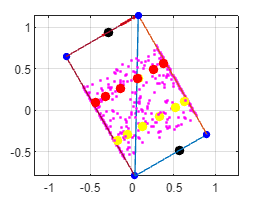

figure
hold on
box on
grid on
axis equal
scatter3(face1_transformed(1, :), face1_transformed(2, :), face1_transformed(3, :), 'm.');
scatter3(face2_transformed(1, :), face2_transformed(2, :), face2_transformed(3, :), 'm.');
scatter3(face3_transformed(1, :), face3_transformed(2, :), face3_transformed(3, :), 'm.');
scatter3(face4_transformed(1, :), face4_transformed(2, :), face4_transformed(3, :), 'm.');
plot3(TrianglePoints(1,[1:3,1]),TrianglePoints(2,[1:3,1]),TrianglePoints(3,[1:3,1]))
plot3(TrianglePoints(1,[4:6,4]),TrianglePoints(2,[4:6,4]),TrianglePoints(3,[4:6,4]))
plot3(TrianglePoints(1,[7:9,7]),TrianglePoints(2,[7:9,7]),TrianglePoints(3,[7:9,7]))
plot3(TrianglePoints(1,[10:12,10]),TrianglePoints(2,[10:12,10]),TrianglePoints(3,[10:12,10]))
plot3(TrianglePoints(1,[13:15,13]),TrianglePoints(2,[13:15,13]),TrianglePoints(3,[13:15,13]))
plot3(TrianglePoints(1,[16:18,16]),TrianglePoints(2,[16:18,16]),TrianglePoints(3,[16:18,16]))
plot3(TrianglePoints(1,[19:21,19]),TrianglePoints(2,[19:21,19]),TrianglePoints(3,[19:21,19]))
plot3(TrianglePoints(1,[22:24,22]),TrianglePoints(2,[22:24,22]),TrianglePoints(3,[22:24,22]))

scatter3(P_bound1(1),P_bound1(2),P_bound1(3),50,'filled','black')
scatter3(P_bound2(1),P_bound2(2),P_bound2(3),50,'filled','black')

scatter3(PP(1,1),PP(1,2),PP(1,3),30,'filled','blue')
scatter3(PP(2,1),PP(2,2),PP(2,3),30,'filled','blue')
scatter3(PP(3,1),PP(3,2),PP(3,3),30,'filled','blue')
scatter3(PP(4,1),PP(4,2),PP(4,3),30,'filled','blue')
scatter3(PP(5,1),PP(5,2),PP(5,3),30,'filled','blue')
scatter3(PP(6,1),PP(6,2),PP(6,3),30,'filled','blue')
scatter3(PP(7,1),PP(7,2),PP(7,3),30,'filled','blue')
scatter3(PP(8,1),PP(8,2),PP(8,3),30,'filled','blue')
quiver3(Pin(1),Pin(2),Pin(3),UPP(1)-Pin(1),UPP(2)-Pin(2),UPP(3)-Pin(3),'--r','LineWidth',2.0)

scatter3(PointTable_A_off(1,:),PointTable_A_off(2,:),PointTable_A_off(3,:),50,'filled','red')
scatter3(PointTable_B_off(1,:),PointTable_B_off(2,:),PointTable_B_off(3,:),50,'filled','yellow')